% Violin Pitch Lab Automation
theta_min = 0;
theta_max = 360;
stepSize = 90;
steps_per_revolution = 200;
positionTheta = (theta_min:stepSize:theta_max)';
positionStep  = positionTheta * (steps_per_revolution/360)';

% Recording Parameters
deviceNum = 0;
sampleRate = 48000; % Hz
bitsPerSample = 16;
numAudioChannels = 1; 
recordTime = 1; % record time in seconds

% Arduino Setup
ArduinoCOMPort = 'COM6';
Arduino = serial(ArduinoCOMPort, 'baudrate', 9600);
fopen(Arduino);
pause(3)
flushinput(Arduino)
%fprintf(Arduino, 'POS:1000');
fprintf(Arduino, 'CAL?');
a = fgetl(Arduino)

a =     '-7050.00
     '


fclose(Arduino);

% Audio Input Settings
info = audiodevinfo;
inputDevices = struct2table(info.input)

inputDevices = 2×3 table
                                   Name                                       DriverVersion        ID
    __________________________________________________________________    _____________________    __

    'Primary Sound Capture Driver (Windows DirectSound)'                  'Windows DirectSound'    0 
    'Microphone (Realtek High Definition Audio) (Windows DirectSound)'    'Windows DirectSound'    1 


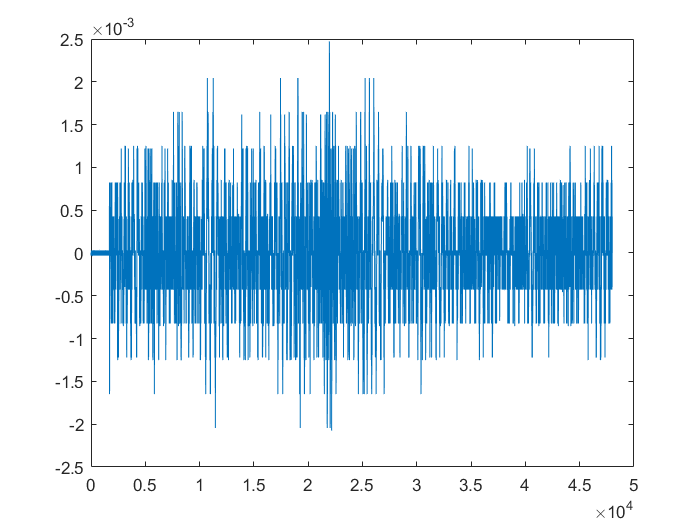

recorder = audiorecorder(sampleRate,bitsPerSample,numAudioChannels,deviceNum);

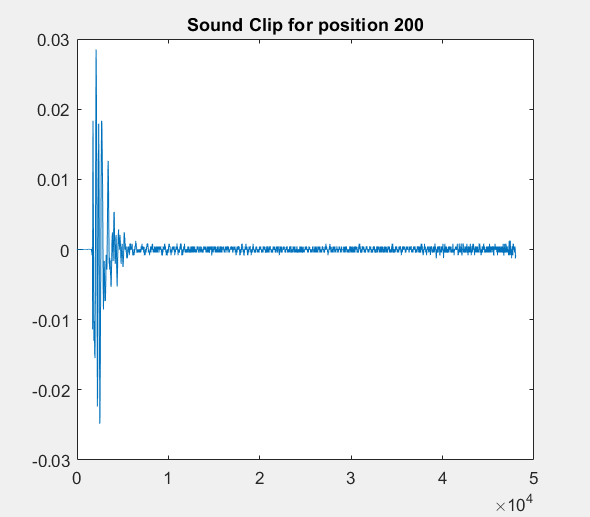

plotbrowser('on')

Iteration 1
Iteration 2
Iteration 3
Iteration 4
Iteration 5


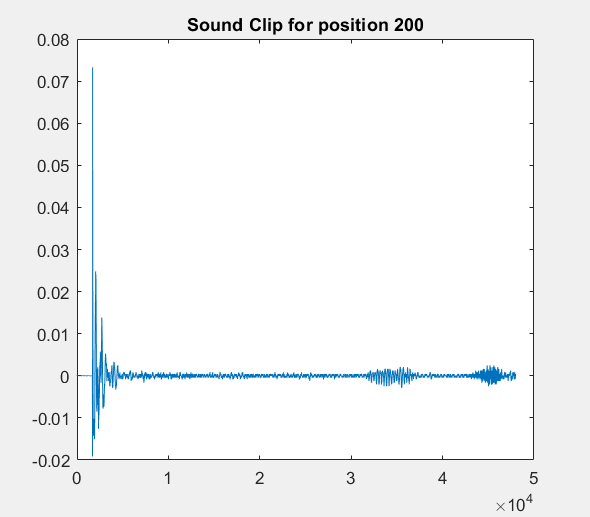


iterations = 1:length(positionStep);
iterations = iterations';
samples = cell(length(positionStep),1);
pitchData = cell(length(positionStep),1);

for i=iterations
    fprintf("Iteration %d\n",i)
    input(sprintf('Click to move to position %d', positionStep(i)));
    % Send move command here
    input(sprintf('Click to read tension'));
    % Read the tension here
    while 1
        input(sprintf('Begin playing and click to record'))
        
        recordblocking(recorder, recordTime);
        %play(recorder);
        y = getaudiodata(recorder);
        plot(y);
        title(sprintf('Sound Clip for position %d',positionStep(i)))
        
        a = input('Recording OK? (y to continue) ','s');
        if a == 'y'
            samples{i} = y;
            break
        end
    end
end


fprintf("Experiment Complete. Closing...");

Experiment Complete. Closing...

% clean up
fclose(Arduino);

fprintf("Done.");

Done.

% Analysis

for i = length(samples)
    s = samples{i}
    [f0,loc] = pitch(s,sampleRate, ...
        'Method','PEF', ...
        'Range',[50 800], ...
        'WindowLength',round(fs*0.08), ...
        'OverlapLength',round(fs*0.05));
    t = loc/fs;
    pitchData{i} = [t,f0]
end

% [f0,loc] = pitch(s,sampleRate, ...
%     'Method','PEF', ...
%     'Range',[50 800], ...
%     'WindowLength',round(fs*0.08), ...
%     'OverlapLength',round(fs*0.05));
% t = loc/fs;
% pitchData{i} = [t,f0]

%ylabel('Pitch (Hz)')
%xlabel('Time (s)')

data = table(iterations,positionStep,positionTheta,samples,pitchData)

data = 5×4 table
    iterations    positionStep    positionTheta        samples     
    __________    ____________    _____________    ________________

    1               0               0              [48000×1 double]
    2              50              90              [48000×1 double]
    3             100             180              [48000×1 double]
    4             150             270              [48000×1 double]
    5             200             360              [48000×1 double]
